Generate msd vs time graphs


%% plot_msd_from_tracks_corrected.m
clear all
close all
% --- USER-DEFINED PARAMETERS ---
ylim_5um   = [0 70]; 
ylim_100um = [0 2.1]; 
xlim_5um   = [0 300];
xlim_100um = [0 300];
deltaT = 3.0;  % Assumed time between frames in seconds

% NEW PARAMETERS FOR FILTERING
skip_first_lag = true;  % Skip lag=1 to avoid initial tracking artifacts
max_displacement_per_frame = 20;  % Maximum allowed displacement in microns per frame
% --------------------------------

rootDir = pwd;
beadFolders = {'5 um redo tracks','100 um tracks'};
conditions  = {'Empty','No Hormones','2 nM E2'};
figure('Color','w'); 
tiledlayout(2,3,'TileSpacing','compact','Padding','compact');
panel = 0;

% Track statistics for diagnostics
total_rejected = 0;
total_accepted = 0;

for b = 1:numel(beadFolders)
    beadPath = findSubdir(rootDir, beadFolders{b});
    if isempty(beadPath)
        warning('Missing bead-size folder: %s', beadFolders{b});
        for c = 1:numel(conditions)
            panel = panel + 1; nexttile(panel);
            title(sprintf('%s — %s', beadFolders{b}, conditions{c}), 'Interpreter','none');
            text(0.5,0.5,'Folder not found','HorizontalAlignment','center');
            axis off;
        end
        continue;
    end
    
    for c = 1:numel(conditions)
        condPath = findSubdir(beadPath, conditions{c});
        panel = panel + 1; 
        nexttile(panel); hold on; grid on;
        
        if isempty(condPath)
            title(sprintf('%s — %s', beadFolders{b}, conditions{c}), 'Interpreter','none');
            text(0.5,0.5,'Condition folder not found','HorizontalAlignment','center');
            axis off; continue;
        end
        
        csvs = dir(fullfile(condPath, '*.csv'));
        if isempty(csvs)
            title(sprintf('%s — %s', beadFolders{b}, conditions{c}), 'Interpreter','none');
            text(0.5,0.5,'No CSV files found','HorizontalAlignment','center');
            axis off; continue;
        end
        
        % Cell array to store squared displacements for each lag
        allD2 = {};
        rejected_count = 0;
        accepted_count = 0;
        
        for k = 1:numel(csvs)
            filePath = fullfile(csvs(k).folder, csvs(k).name);
            T = readTrackMateCSV(filePath);
            
            % Use FRAME column if it exists, otherwise approximate it from POSITION_T
            if ~ismember('FRAME', T.Properties.VariableNames)
                T.FRAME = round(T.POSITION_T / deltaT);
            end

            T = T(isfinite(T.TRACK_ID) & isfinite(T.POSITION_X) & ...
                  isfinite(T.POSITION_Y) & isfinite(T.FRAME), :);
            if height(T) < 2, continue; end
            
            % Process each track
            trackIDs = unique(T.TRACK_ID);
            for ti = 1:length(trackIDs)
                idx = (T.TRACK_ID == trackIDs(ti));
                Ttrack = T(idx, :);
                if height(Ttrack) < 2, continue; end
                
                Ttrack = sortrows(Ttrack, 'FRAME');
                
                x = Ttrack.POSITION_X;
                y = Ttrack.POSITION_Y;
                frames = Ttrack.FRAME;
                n = height(Ttrack);
                
                % MODIFIED MSD CALCULATION WITH FILTERING
                for i = 1:(n-1)
                    for j = (i+1):n
                        lag = frames(j) - frames(i);
                        
                        % Skip lag=1 if requested
                        if skip_first_lag && lag == 1
                            continue;
                        end
                        
                        % Calculate displacement
                        dx = x(j) - x(i);
                        dy = y(j) - y(i);
                        displacement = sqrt(dx^2 + dy^2);
                        
                        % Check if displacement per frame exceeds threshold
                        displacement_per_frame = displacement / lag;
                        if displacement_per_frame > max_displacement_per_frame
                            rejected_count = rejected_count + 1;
                            % Skip this data point - it's likely a tracking error
                            continue;
                        end
                        
                        accepted_count = accepted_count + 1;
                        d2 = dx^2 + dy^2;
                        
                        if lag > 0
                            if lag > length(allD2)
                                allD2{lag} = d2;
                            else
                                allD2{lag} = [allD2{lag}; d2];
                            end
                        end
                    end
                end
            end
        end
        
        % Print diagnostic info
        fprintf('\n%s - %s:\n', beadFolders{b}, conditions{c});
        fprintf('  Rejected %d displacement measurements (%.1f%%)\n', ...
            rejected_count, 100*rejected_count/(rejected_count+accepted_count+eps));
        fprintf('  Accepted %d displacement measurements\n', accepted_count);
        
        total_rejected = total_rejected + rejected_count;
        total_accepted = total_accepted + accepted_count;
        
        if isempty(allD2)
            title(sprintf('%s — %s', beadFolders{b}, conditions{c}), 'Interpreter','none');
            text(0.5,0.5,'No usable track data','HorizontalAlignment','center');
            axis off; continue;
        end
        
        % Calculate mean MSD at each lag
        maxLag = length(allD2);
        lags = (1:maxLag)';
        msd = zeros(maxLag, 1);
        n_points = zeros(maxLag, 1);
        
        for lag = 1:maxLag
            if ~isempty(allD2{lag})
                msd(lag) = mean(allD2{lag});
                n_points(lag) = length(allD2{lag});
            end
        end
        
        % Remove any zero entries that might result from empty cells
        valid_idx = msd > 0;
        msd = msd(valid_idx);
        lags = lags(valid_idx);
        n_points = n_points(valid_idx);

        % Convert lags to time
        time = lags * deltaT;
        
        % Add origin point for physical consistency
        time = [0; time];
        msd = [0; msd];
        
        % Plot
        plot(time, msd, '-', 'LineWidth', 1.5);
        xlabel('Time (s)');
        ylabel('MSD (\mum^2)', 'Interpreter','tex');
        title(sprintf('%s — %s', beadFolders{b}, conditions{c}), 'Interpreter','none');
        
        % Add text annotation showing filtering applied
        if skip_first_lag
            text(0.02, 0.98, sprintf('Filtered: >%.0f μm/frame, skip lag 1', max_displacement_per_frame), ...
                'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 8, 'Color', 'b');
        else
            text(0.02, 0.98, sprintf('Filtered: >%.0f μm/frame', max_displacement_per_frame), ...
                'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 8, 'Color', 'b');
        end
        
        % Apply limits
        if contains(beadFolders{b}, '5 um', 'IgnoreCase', true)
            xlim(xlim_5um);
            ylim(ylim_5um);
        elseif contains(beadFolders{b}, '100 um', 'IgnoreCase', true)
            xlim(xlim_100um);
            ylim(ylim_100um);
        end
    end
end


5 um redo tracks - Empty:


  Rejected 0 displacement measurements (0.0


% Print overall statistics
fprintf('\n=== OVERALL STATISTICS ===\n');
fprintf('Total rejected: %d (%.1f%%)\n', total_rejected, ...
    100*total_rejected/(total_rejected+total_accepted+eps));
fprintf('Total accepted: %d\n', total_accepted);
fprintf('Threshold used: %.1f microns per frame\n', max_displacement_per_frame);




Test tracks just to see if they are looking ok

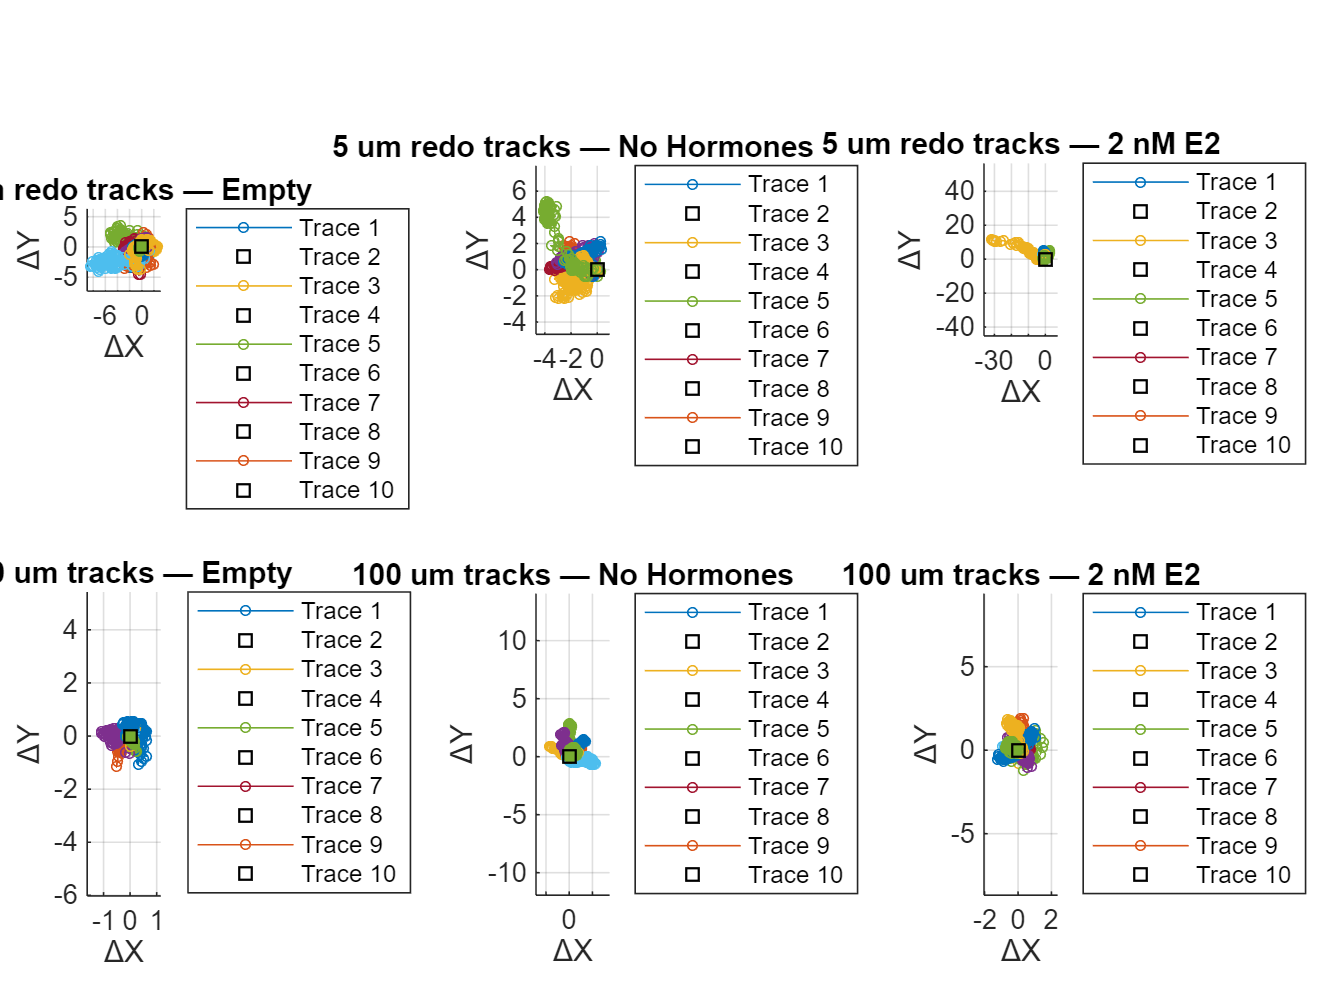


%% plot_normalized_traces_from_tracks.m
clear all; close all;

% --- USER PARAMETERS ---
deltaT = 3.0;                 % seconds per frame (only used if FRAME missing)
maxTracesToPlot = 10;         % per panel
beadFolders = {'5 um redo tracks','100 um tracks'};
conditions  = {'Empty','No Hormones','2 nM E2'};
rootDir = pwd;
% ------------------------

figure('Color','w');
tiledlayout(numel(beadFolders), numel(conditions), ...
    'TileSpacing','compact','Padding','compact');

panel = 0;
for b = 1:numel(beadFolders)
    beadPath = findSubdir(rootDir, beadFolders{b});
    for c = 1:numel(conditions)
        panel = panel + 1; nexttile(panel); hold on; grid on;
        title(sprintf('%s — %s', beadFolders{b}, conditions{c}), 'Interpreter','none');
        xlabel('\DeltaX'); ylabel('\DeltaY');

        if isempty(beadPath), axis off; continue; end
        condPath = findSubdir(beadPath, conditions{c});
        if isempty(condPath), axis off; continue; end

        csvs = dir(fullfile(condPath, '*.csv'));
        if isempty(csvs), axis off; continue; end

        % --- Collect all tracks across CSVs ---
        tracks = {};  % each cell: table for one track
        for k = 1:numel(csvs)
            filePath = fullfile(csvs(k).folder, csvs(k).name);
            T = readTrackMateCSV(filePath);

            % FRAME fallback if missing
            if ~ismember('FRAME', T.Properties.VariableNames)
                T.FRAME = round(T.POSITION_T / deltaT);
            end

            T = T(isfinite(T.TRACK_ID) & isfinite(T.POSITION_X) & ...
                  isfinite(T.POSITION_Y) & isfinite(T.FRAME), :);
            if height(T) < 2, continue; end

            trackIDs = unique(T.TRACK_ID);
            for ti = 1:numel(trackIDs)
                idx = (T.TRACK_ID == trackIDs(ti));
                Ttrack = sortrows(T(idx,:), 'FRAME');
                if height(Ttrack) >= 2
                    tracks{end+1} = Ttrack; %#ok<AGROW>
                end
            end
        end

        if isempty(tracks)
            text(0.5,0.5,'No usable tracks','HorizontalAlignment','center');
            axis off; continue;
        end

        % --- Pick up to maxTracesToPlot longest tracks ---
        lens = cellfun(@(Tt) height(Tt), tracks);
        [~, order] = sort(lens, 'descend');
        pick = order(1:min(maxTracesToPlot, numel(order)));

        % --- Plot each selected track, re-anchored at (0,0) ---
        for pidx = pick(:)'
            Tt = tracks{pidx};
            x = Tt.POSITION_X;  y = Tt.POSITION_Y;
            x0 = x(1);          y0 = y(1);
            dx = x - x0;        dy = y - y0;

            plot(dx, dy, '-o', 'MarkerSize', 3);         % full path
            plot(0, 0, 'ks', 'MarkerSize', 5, 'LineWidth', 1);  % origin marker
        end

        axis equal;
        % Optional: auto-tight limits with a small margin
        xl = xlim; yl = ylim;
        pad = 0.05 * max(diff(xl), diff(yl));
        xlim([xl(1)-pad, xl(2)+pad]); ylim([yl(1)-pad, yl(2)+pad]);
        legend(sprintfc('Trace %d', 1:numel(pick)), 'Location','bestoutside'); %#ok<*NOPRT>
    end
end

Functions




%% Helper functions (same as before)
function p = findSubdir(parent, targetName)

Function 'findSubdir' has already been declared within this scope.

    p = "";
    if ~isfolder(parent), return; end
    L = dir(parent);
    isdir = [L.isdir];
    names = {L(isdir).name};
    names = names(~ismember(lower(names), {'.','..'}));
    if isempty(names), return; end
    match = strcmpi(names, targetName);
    if any(match)
        p = fullfile(parent, names{find(match,1)});
    else
        match = contains(lower(names), lower(targetName));
        if any(match), p = fullfile(parent, names{find(match,1)}); end
    end
end

function T = readTrackMateCSV(filePath)
    opts = detectImportOptions(filePath, 'NumHeaderLines', 0);
    opts.VariableNamesLine = 1;
    opts.DataLines = [4, inf];  % TrackMate: headers+units in first 3 lines
    enforce = {'TRACK_ID','POSITION_X','POSITION_Y','POSITION_T'};
    for i = 1:numel(enforce)
        if any(strcmp(opts.VariableNames, enforce{i}))
            opts = setvartype(opts, enforce{i}, 'double');
        end
    end
    T = readtable(filePath, opts);
end










